# HW6

Ali Ramezanzadeh 40023131

% Sampling time
Ts = 0.1;

% Total simulation time
T_total = 40; % seconds

% Time vector
t_vec = 0:Ts:T_total;
T = length(t_vec);

% True theta (unknown to estimator)
theta_true = [0; 0.01; 0; 2; 0; 1];

% Input: white noise
u = randn(T,1);

% Initialize output y
y = zeros(T,1);

% Number of parameters
n_params = 6;

## Part (i)

Projection algorithm

% Initialize theta_hat
theta_hat = zeros(6,T); % Each column is estimate at time t
theta_hat(:,1) = zeros(6,1); % initial guess

% Initialize estimated output for plotting
y_hat = zeros(T,1);

for t = 1:T
    % Build phi(t)
    phi = zeros(6,1);
    if t >= 2
        phi(1) = y(t-1);
        phi(6) = u(t-1);
    end
    if t >= 3
        phi(2) = y(t-2);
        phi(5) = u(t-2);
    end
    if t >= 4
        phi(3) = y(t-3);
        phi(4) = u(t-3);
    end

    % Compute true output
    y(t) = theta_true' * phi;

    % For t=1, no estimation update yet
    if t==1
        continue
    end

    % Compute prediction error
    e = y(t) - phi' * theta_hat(:,t-1);

    % Normalization denominator
    denom = phi' * phi;
    if denom < 1e-8
        denom = 1e-8; % avoid division by zero
    end

    % Update theta_hat
    theta_hat(:,t) = theta_hat(:,t-1) + (phi / denom) * e;

    % Estimated output for comparison
    y_hat(t) = phi' * theta_hat(:,t-1);
end

disp('Final estimated parameters:');

Final estimated parameters:


disp(theta_hat(:,t))

    0.0000
    0.0100
   -0.0000
    2.0000
   -0.0000
    1.0000



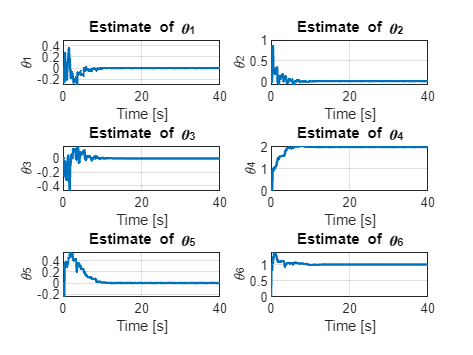


% Plot estimated parameters over time
figure;
for k = 1:6
    subplot(3,2,k);
    plot(t_vec, theta_hat(k,:), 'LineWidth',1.5);
    xlabel('Time [s]');
    ylabel(['\theta_',num2str(k)]);
    title(['Estimate of \theta_',num2str(k)]);
    grid on;
end

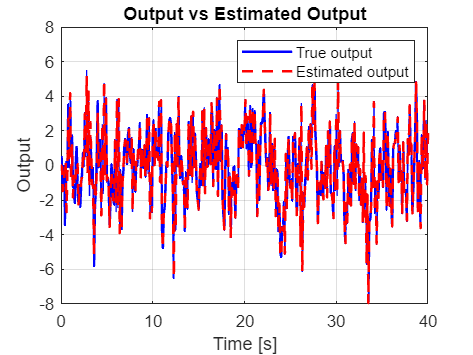


% Plot output vs estimated output
figure;
plot(t_vec, y, 'b', 'LineWidth',1.5); hold on;
plot(t_vec, y_hat, 'r--','LineWidth',1.5);
xlabel('Time [s]');
ylabel('Output');
legend('True output','Estimated output');
title('Output vs Estimated Output');
grid on;;

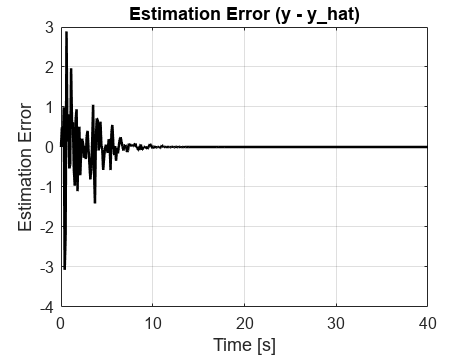


% Compute error
error = y - y_hat;

% Plot error
figure;
plot(t_vec, error, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Estimation Error');
title('Estimation Error (y - y\_hat)');
grid on;

OPA

% Initial theta_hat
theta_hat = zeros(n_params,T);
theta_hat(:,1) = zeros(n_params,1);

% OPA initial P: P(-2) = I
P_prev2 = eye(n_params);

% Initialize estimated output
y_hat = zeros(T,1);

for t = 1:T
    % Build phi(t)
    phi = zeros(n_params,1);
    if t >= 2
        phi(1) = y(t-1);
        phi(6) = u(t-1);
    end
    if t >= 3
        phi(2) = y(t-2);
        phi(5) = u(t-2);
    end
    if t >= 4
        phi(3) = y(t-3);
        phi(4) = u(t-3);
    end

    % Compute true output
    y(t) = theta_true' * phi;

    % Skip update if t==1 (no previous estimates)
    if t==1
        continue
    end

    % Compute prediction error
    e = y(t) - phi' * theta_hat(:,t-1);

    % Denominator (note: no "+1")
    denom = phi' * P_prev2 * phi;

    % To avoid division by zero
    if denom < 1e-5
        denom = 1e-5;
    end

    % Update theta_hat
    theta_hat(:,t) = theta_hat(:,t-1) + (P_prev2 * phi / denom) * e;

    % Update P
    P_new = P_prev2 - (P_prev2 * phi * phi' * P_prev2) / denom;

    % Save P(t-1) for next iteration
    P_prev2 = P_new;

    % Store estimated output
    y_hat(t) = phi' * theta_hat(:,t-1);
end

disp('Final estimated parameters:');

Final estimated parameters:


disp(theta_hat(:,t))

    0.0000
    0.0100
   -0.0000
    2.0000
   -0.0000
    1.0000



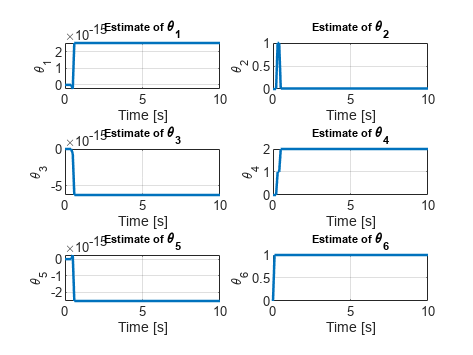


% Plot estimated parameters over time
figure;
for kidx = 1:n_params
    subplot(3,2,kidx);
    plot(t_vec, theta_hat(kidx,:), 'LineWidth',1.5);
    xlabel('Time [s]');
    ylabel(['\theta_',num2str(kidx)]);
    title(['Estimate of \theta_',num2str(kidx)]);
    xlim([0 10]);
    grid on;
end

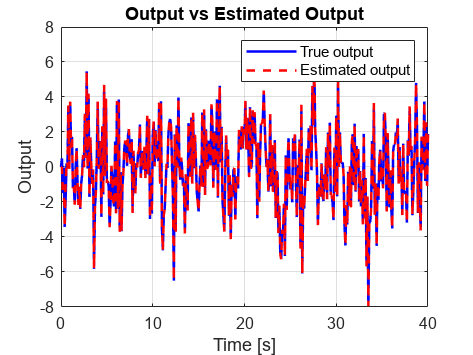


% Plot output vs estimated output
figure;
plot(t_vec, y, 'b', 'LineWidth',1.5); hold on;
plot(t_vec, y_hat, 'r--', 'LineWidth',1.5);
xlabel('Time [s]');
ylabel('Output');
legend('True output','Estimated output');
title('Output vs Estimated Output');
grid on;

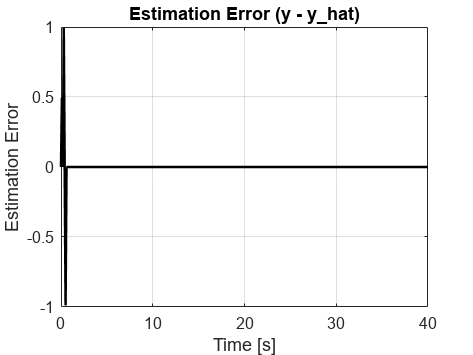


% Compute error
error = y - y_hat;

% Plot error
figure;
plot(t_vec, error, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Estimation Error');
title('Estimation Error (y - y\_hat)');
grid on;

RLS (Recursive Least Square)

% Initial theta_hat
theta_hat = zeros(n_params,T);
theta_hat(:,1) = zeros(n_params,1);

% RLS initial P: P(-2) = (1/k) * I
k = 10; 
P_prev2 = (1/k) * eye(n_params);

% Initialize estimated output
y_hat = zeros(T,1);

for t = 1:T
    % Build phi(t)
    phi = zeros(n_params,1);
    if t >= 2
        phi(1) = y(t-1);
        phi(6) = u(t-1);
    end
    if t >= 3
        phi(2) = y(t-2);
        phi(5) = u(t-2);
    end
    if t >= 4
        phi(3) = y(t-3);
        phi(4) = u(t-3);
    end

    % Compute true output
    y(t) = theta_true' * phi;

    % Skip update if t==1 (no previous estimates)
    if t==1
        continue
    end

    % Compute prediction error
    e = y(t) - phi' * theta_hat(:,t-1);

    % Denominator
    denom = 1 + phi' * P_prev2 * phi;

    % Update gain
    K = (P_prev2 * phi) / denom;

    % Update theta_hat
    theta_hat(:,t) = theta_hat(:,t-1) + K * e;

    % Update P
    P_new = P_prev2 - (K * phi' * P_prev2);

    % Save P(t-1) for next iteration
    P_prev2 = P_new;

    % Store estimated output
    y_hat(t) = phi' * theta_hat(:,t-1);
end

disp('Final estimated parameters:');

Final estimated parameters:


disp(theta_hat(:,t))

    0.0024
    0.0257
   -0.0025
    1.9289
    0.0057
    0.9782



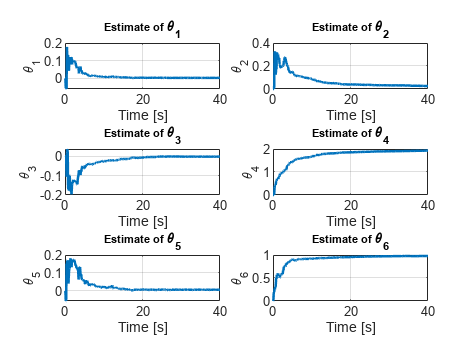


% Plot estimated parameters over time
figure;
for kidx = 1:n_params
    subplot(3,2,kidx);
    plot(t_vec, theta_hat(kidx,:), 'LineWidth',1.5);
    xlabel('Time [s]');
    ylabel(['\theta_',num2str(kidx)]);
    title(['Estimate of \theta_',num2str(kidx)]);
    grid on;
end

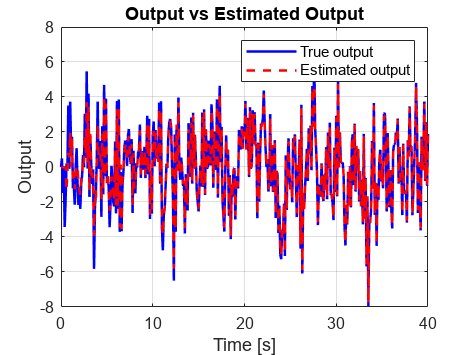


% Plot output vs estimated output
figure;
plot(t_vec, y, 'b', 'LineWidth',1.5); hold on;
plot(t_vec, y_hat, 'r--', 'LineWidth',1.5);
xlabel('Time [s]');
ylabel('Output');
legend('True output','Estimated output');
title('Output vs Estimated Output');
grid on;

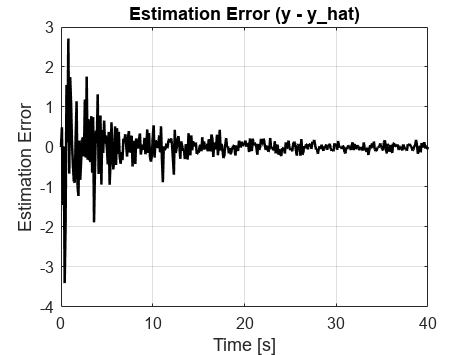


% Compute error
error = y - y_hat;

% Plot error
figure;
plot(t_vec, error, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Estimation Error');
title('Estimation Error (y - y\_hat)');
grid on;

## Part (ii)

Selective Data Weighting RLS

% Initial theta_hat
theta_hat = zeros(n_params,T);
theta_hat(:,1) = zeros(n_params,1);

% RLS initial P
k = 10;  % You can set k here
P_prev2 = (1/k)*eye(n_params);

% Initialize estimated output
y_hat = zeros(T,1);

% Threshold for data weight
delta = 1e-3;

for t = 1:T
    % Build phi(t)
    phi = zeros(n_params,1);
    if t >= 2
        phi(1) = y(t-1);
        phi(6) = u(t-1);
    end
    if t >= 3
        phi(2) = y(t-2);
        phi(5) = u(t-2);
    end
    if t >= 4
        phi(3) = y(t-3);
        phi(4) = u(t-3);
    end

    % Compute true output
    y(t) = theta_true' * phi;

    % Skip update if t==1
    if t==1
        continue
    end

    % Compute prediction error
    e = y(t) - phi' * theta_hat(:,t-1);

    % Compute phi' * P * phi
    num = phi' * P_prev2 * phi;

    % Selective weighting

    if num >= delta
        a = 40;
    else
        a = 0.1;
    end

    % Denominator
    denom = 1 + a * num;

    % Update gain
    K = (a * P_prev2 * phi) / denom;

    % Update theta_hat
    theta_hat(:,t) = theta_hat(:,t-1) + K * e;

    % Update P
    P_new = P_prev2 - (K * phi' * P_prev2);

    % Save P for next iteration
    P_prev2 = P_new;

    % Store estimated output
    y_hat(t) = phi' * theta_hat(:,t-1);
end
disp('Final estimated parameters:');

Final estimated parameters:


disp(theta_hat(:,t))

    0.0001
    0.0106
   -0.0001
    1.9972
    0.0003
    0.9991



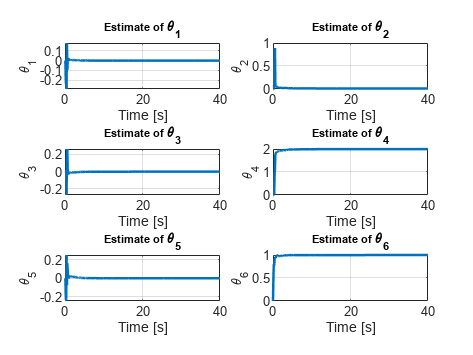


% Plot estimated parameters over time
figure;
for kidx = 1:n_params
    subplot(3,2,kidx);
    plot(t_vec, theta_hat(kidx,:), 'LineWidth',1.5);
    xlabel('Time [s]');
    ylabel(['\theta_',num2str(kidx)]);
    title(['Estimate of \theta_',num2str(kidx)]);
    grid on;
end

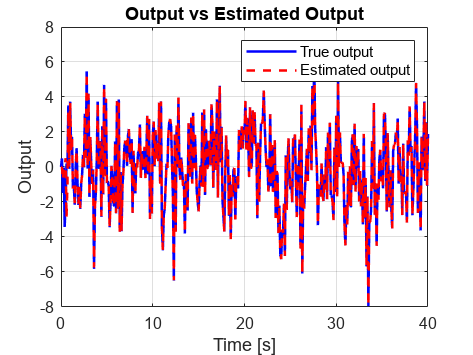


% Plot output vs estimated output
figure;
plot(t_vec, y, 'b', 'LineWidth',1.5); hold on;
plot(t_vec, y_hat, 'r--', 'LineWidth',1.5);
xlabel('Time [s]');
ylabel('Output');
legend('True output','Estimated output');
title('Output vs Estimated Output');
grid on;

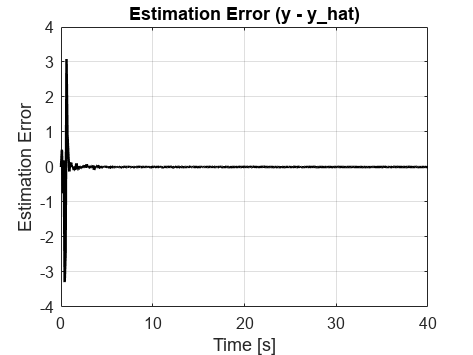


% Compute error
error = y - y_hat;

% Plot error
figure;
plot(t_vec, error, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Estimation Error');
title('Estimation Error (y - y\_hat)');
grid on;

Exponential Data Weighting RLS

% Initial theta_hat
theta_hat = zeros(n_params, T);
theta_hat(:,1) = zeros(n_params, 1);

% Initial P
P_prev2 = eye(n_params);  % P(-2)

% Initial alpha values
alpha0 = 0.99;   % constant forgetting factor
alpha = zeros(T,1);
alpha(1) = 0.95;

% Initialize estimated output
y_hat = zeros(T,1);

for t = 1:T
    % Build phi(t-1)
    phi = zeros(n_params,1);
    if t >= 2
        phi(1) = y(t-1);
        phi(6) = u(t-1);
    end
    if t >= 3
        phi(2) = y(t-2);
        phi(5) = u(t-2);
    end
    if t >= 4
        phi(3) = y(t-3);
        phi(4) = u(t-3);
    end

    % Compute true output
    y(t) = theta_true' * phi;

    if t == 1
        continue
    end

    % Compute alpha(t-1)
    alpha(t) = alpha0 * alpha(t-1) + (1 - alpha0);

    % Prediction error using phi(t-1), theta(t-1)
    e = y(t) - phi' * theta_hat(:,t-1);

    % Denominator
    denom = alpha(t-1) + phi' * P_prev2 * phi;

    % To avoid division by zero
    if denom < 1e-8
        denom = 1e-8;
    end

    % Gain
    K = P_prev2 * phi / denom;

    % Update theta
    theta_hat(:,t) = theta_hat(:,t-1) + K * e;

    % Update P
    P_new = (1 / alpha(t-1)) * (P_prev2 - (K * phi' * P_prev2));

    % Store estimated output
    y_hat(t) = phi' * theta_hat(:,t-1);

    % Update P_prev2
    P_prev2 = P_new;
end
disp('Final estimated parameters:');

Final estimated parameters:


disp(theta_hat(:,end))

    0.0000
    0.0100
   -0.0000
    1.9999
    0.0000
    1.0000



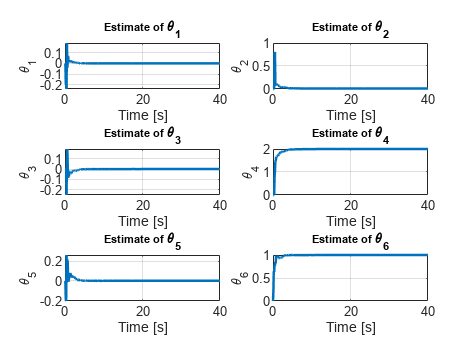


% Plot estimated parameters
figure;
for k = 1:n_params
    subplot(3,2,k);
    plot(t_vec, theta_hat(k,:), 'LineWidth',1.5);
    xlabel('Time [s]');
    ylabel(['\theta_',num2str(k)]);
    title(['Estimate of \theta_',num2str(k)]);
    grid on;
end

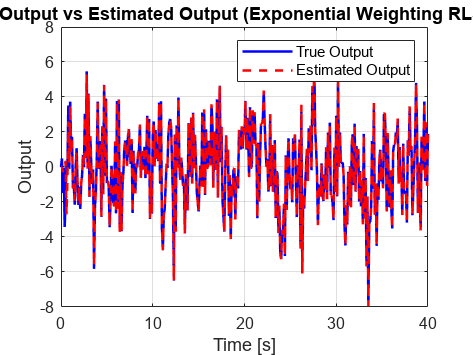


% Plot output comparison
figure;
plot(t_vec, y, 'b', 'LineWidth',1.5); hold on;
plot(t_vec, y_hat, 'r--', 'LineWidth',1.5);
xlabel('Time [s]');
ylabel('Output');
legend('True Output','Estimated Output');
title('Output vs Estimated Output (Exponential Weighting RLS)');
grid on;

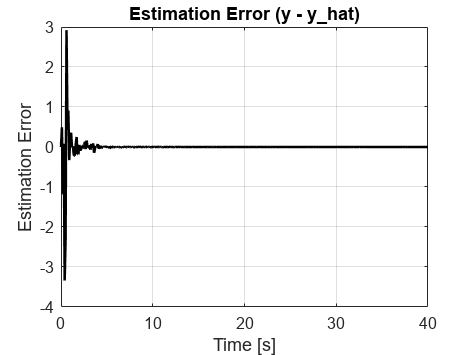


% Compute error
error = y - y_hat;

% Plot error
figure;
plot(t_vec, error, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Estimation Error');
title('Estimation Error (y - y\_hat)');
grid on;

Covariance Resseting 

% RLS initial covariance matrix: P(-2) = (1/k)*I
k_init = 2;
P_reset = (1/k_init)*eye(n_params);
P_prev = P_reset;

% Initialize estimated parameters
theta_hat = zeros(n_params,T);
theta_hat(:,1) = zeros(n_params,1);

% Initialize estimated output
y_hat = zeros(T,1);

% Reset interval (every N samples)
reset_interval = 5; 

%% MAIN LOOP
for t = 1:T

    % Build regressor vector phi(t-1)
    phi = zeros(n_params,1);
    if t >= 2
        phi(1) = y(t-1);
        phi(6) = u(t-1);
    end
    if t >= 3
        phi(2) = y(t-2);
        phi(5) = u(t-2);
    end
    if t >= 4
        phi(3) = y(t-3);
        phi(4) = u(t-3);
    end

    % Compute true output
    y(t) = theta_true' * phi;

    % Skip parameter update if t==1
    if t==1
        theta_hat(:,t) = theta_hat(:,1);
        y_hat(t) = 0;
        continue
    end

    % Prediction error
    e = y(t) - phi' * theta_hat(:,t-1);

    % Denominator
    denom = 1 + phi' * P_prev * phi;

    % RLS gain vector
    K = (P_prev * phi) / denom;

    % Update parameter estimate
    theta_hat(:,t) = theta_hat(:,t-1) + K * e;

    % Update covariance matrix
    P_new = P_prev - (K * phi' * P_prev);

    % Check if reset is needed
    if mod(t,reset_interval) == 0
        P_new = P_reset;  % Reset covariance
        disp(['Resetting covariance at iteration t = ', num2str(t)]);
    end

    % Save P for next iteration
    P_prev = P_new;

    % Estimated output
    y_hat(t) = phi' * theta_hat(:,t);
end

Resetting covariance at iteration t = 5
Resetting covariance at iteration t = 10
Resetting covariance at iteration t = 15
Resetting covariance at iteration t = 20
Resetting covariance at iteration t = 25
Resetting covariance at iteration t = 30
Resetting covariance at iteration t = 35
Resetting covariance at iteration t = 40
Resetting covariance at iteration t = 45
Resetting covariance at iteration t = 50
Resetting covariance at iteration t = 55
Resetting covariance at iteration t = 60
Resetting covariance at iteration t = 65
Resetting covariance at iteration t = 70
Resetting covariance at iteration t = 75
Resetting covariance at iteration t = 80
Resetting covariance at iteration t = 85
Resetting covariance at iteration t = 90
Resetting covariance at iteration t = 95
Resetting covariance at iteration t = 100
Resetting covariance at iteration t = 105
Resetting covariance at iteration t = 110
Resetting covariance at iteration t = 115
Resetting covariance at iteration t = 120
Resetting co


%% Display final parameter estimates
disp('Final estimated parameters:');

Final estimated parameters:


disp(theta_hat(:,end));

   -0.0000
    0.0100
    0.0000
    2.0000
    0.0000
    1.0000



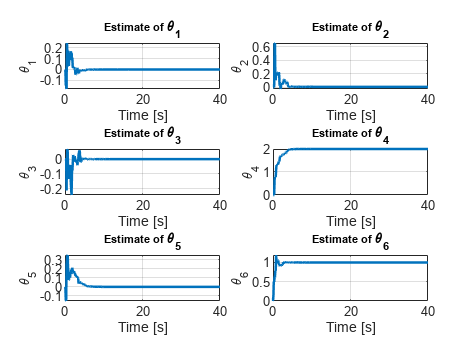


%% Plot estimated parameters over time
figure;
for kidx = 1:n_params
    subplot(3,2,kidx);
    plot(t_vec, theta_hat(kidx,:), 'LineWidth',1.5);
    xlabel('Time [s]');
    ylabel(['\theta_',num2str(kidx)]);
    title(['Estimate of \theta_',num2str(kidx)]);
    grid on;
end

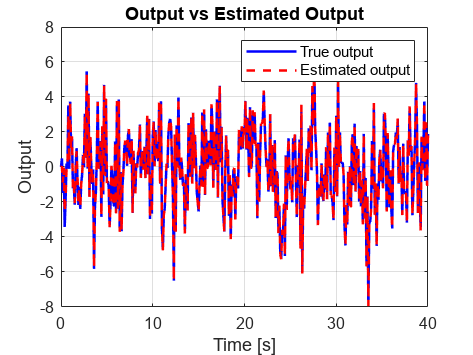


%% Plot output vs estimated output
figure;
plot(t_vec, y, 'b', 'LineWidth',1.5); hold on;
plot(t_vec, y_hat, 'r--', 'LineWidth',1.5);
xlabel('Time [s]');
ylabel('Output');
legend('True output','Estimated output');
title('Output vs Estimated Output');
grid on;

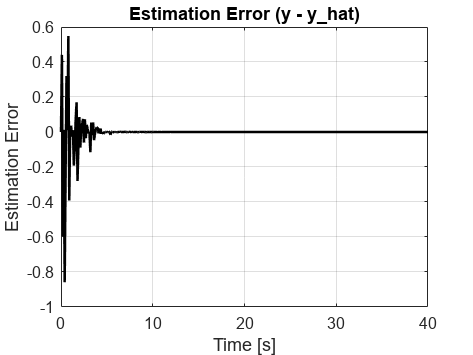


% Compute error
error = y - y_hat;

% Plot error
figure;
plot(t_vec, error, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Estimation Error');
title('Estimation Error (y - y\_hat)');
grid on;

## Part (iii)

New Parameters

% Fixed parameters (b1, b2, b3)
b_values = [2; 0; 1];

% Preallocate theta_true for each time step
theta_true = zeros(n_params, T);

% Generate time-varying theta_true
for t_idx = 1:T
    t_curr = t_vec(t_idx);
    
    % Determine a1, a2, a3 based on t (seconds)
    if t_curr <=3
        a = [0; -0.1; 0];
    elseif t_curr <=6
        a = [0.1; 0; -0.2];
    elseif t_curr <=9
        a = [0; 0.1; 0];
    else
        a = [0.1; 0; -0.1];
    end
    
    theta_true(:, t_idx) = [a; b_values];
end

Covariance Modification RLS

% --- Initialize estimates ---
theta_hat = zeros(n_params, T);
theta_hat(:,1) = zeros(n_params,1);

% --- Initialize covariance ---
P_prev = 1000*eye(n_params);   % Large initial covariance

% --- Forgetting factor coefficient for Q(t) ---
lambda_Q = 0.3;

% --- Loop ---
for i = 1:T
    % Build phi(t)
    phi = zeros(n_params,1);
    if i >=2
        phi(1) = y(i-1);
        phi(6) = u(i-1);
    end
    if i >=3
        phi(2) = y(i-2);
        phi(5) = u(i-2);
    end
    if i >=4
        phi(3) = y(i-3);
        phi(4) = u(i-3);
    end

    % Compute true output
    y(i) = theta_true(:,i)' * phi;

    if i==1
        continue
    end

    % Prediction error
    e = y(i) - phi' * theta_hat(:,i-1);

    % Gain
    denom = 1 + phi' * P_prev * phi;
    K = (P_prev * phi) / denom;

    % Update theta
    theta_hat(:,i) = theta_hat(:,i-1) + K * e;

    % Covariance update
    P_tilde = P_prev - K * phi' * P_prev;
    Q = lambda_Q * e^2 * eye(n_params);
    P_new = P_tilde + Q;

    % Estimated output
    y_hat(i) = phi' * theta_hat(:,i-1);

    % Save covariance for next iteration
    P_prev = P_new;
end

% --- Display final estimates ---
disp('Final estimated parameters:');

Final estimated parameters:


disp(theta_hat(:,end));

    0.0996
    0.0001
   -0.0997
    2.0000
    0.0008
    0.9998



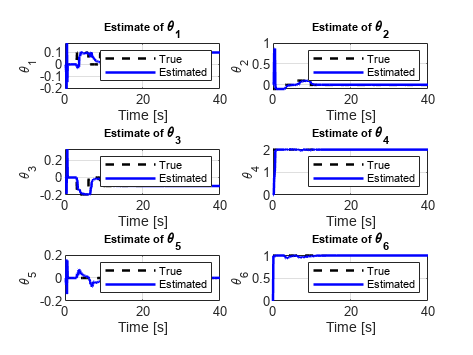


% --- Plot estimated parameters over time ---
figure;
for k = 1:n_params
    subplot(3,2,k);
    plot(t_vec, theta_true(k,:), 'k--','LineWidth',1.5); hold on;
    plot(t_vec, theta_hat(k,:), 'b','LineWidth',1.5);
    xlabel('Time [s]');
    ylabel(['\theta_', num2str(k)]);
    legend('True','Estimated');
    title(['Estimate of \theta_', num2str(k)]);
    grid on;
end

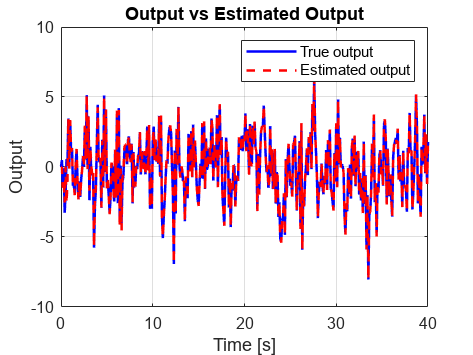


% --- Plot output vs estimated output ---
figure;
plot(t_vec, y, 'b','LineWidth',1.5); hold on;
plot(t_vec, y_hat, 'r--','LineWidth',1.5);
xlabel('Time [s]');
ylabel('Output');
legend('True output','Estimated output');
title('Output vs Estimated Output');
grid on;

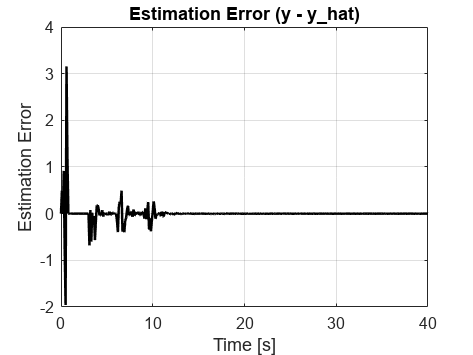


% Compute error
error = y - y_hat;

% Plot error
figure;
plot(t_vec, error, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Estimation Error');
title('Estimation Error (y - y\_hat)');
grid on;

PA

% --- Initialize parameter estimates ---
theta_hat = zeros(n_params,T);
theta_hat(:,1) = zeros(n_params,1);

% --- Projection algorithm loop ---
for i = 1:T
    % Build regressor phi(t)
    phi = zeros(n_params,1);
    if i >=2
        phi(1) = y(i-1);
        phi(6) = u(i-1);
    end
    if i >=3
        phi(2) = y(i-2);
        phi(5) = u(i-2);
    end
    if i >=4
        phi(3) = y(i-3);
        phi(4) = u(i-3);
    end

    % Compute true output with current theta_true
    y(i) = theta_true(:,i)' * phi;

    if i==1
        continue
    end

    % Prediction error
    e = y(i) - phi' * theta_hat(:,i-1);

    % Normalization denominator
    denom = phi' * phi;
    if denom < 1e-8
        denom = 1e-8;
    end

    % Update theta_hat
    theta_hat(:,i) = theta_hat(:,i-1) + (phi / denom) * e;

    % Estimated output (using previous theta_hat)
    y_hat(i) = phi' * theta_hat(:,i-1);
end

% --- Display final estimates ---
disp('Final estimated parameters:');

Final estimated parameters:


disp(theta_hat(:,end));

    0.1000
    0.0000
   -0.1000
    2.0000
   -0.0000
    1.0000



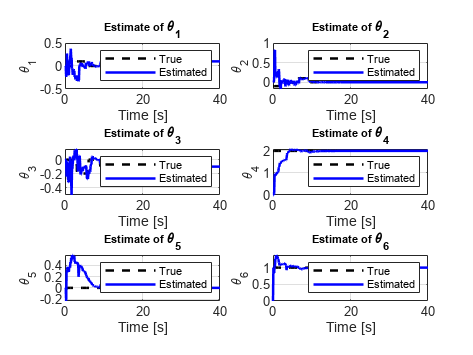


% --- Plot estimated parameters over time ---
figure;
for k = 1:n_params
    subplot(3,2,k);
    plot(t_vec, theta_true(k,:), 'k--','LineWidth',1.5); hold on;
    plot(t_vec, theta_hat(k,:), 'b','LineWidth',1.5);
    xlabel('Time [s]');
    ylabel(['\theta_', num2str(k)]);
    legend('True','Estimated');
    title(['Estimate of \theta_', num2str(k)]);
    grid on;
end

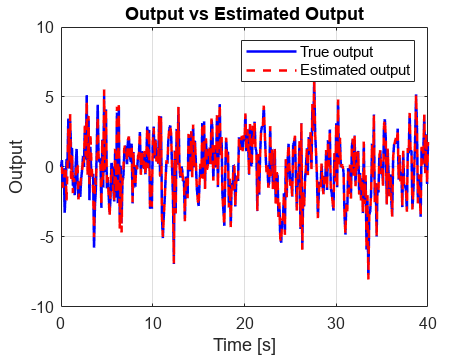


% --- Plot output vs estimated output ---
figure;
plot(t_vec, y, 'b','LineWidth',1.5); hold on;
plot(t_vec, y_hat, 'r--','LineWidth',1.5);
xlabel('Time [s]');
ylabel('Output');
legend('True output','Estimated output');
title('Output vs Estimated Output');
grid on;

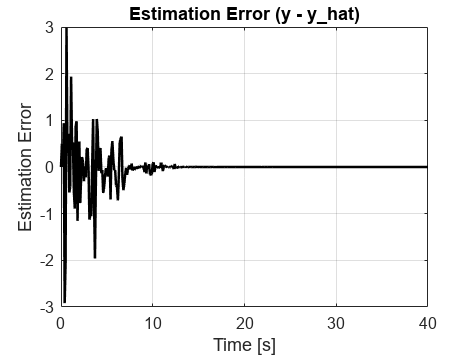


% Compute error
error = y - y_hat;

% Plot error
figure;
plot(t_vec, error, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Estimation Error');
title('Estimation Error (y - y\_hat)');
grid on;

OPA

% Initialize theta_hat
theta_hat = zeros(n_params,T);
theta_hat(:,1) = zeros(n_params,1);

% OPA initial covariance P(-2) = Identity matrix
P_prev = eye(n_params);

% Main estimation loop
for t_idx = 1:T
    % Build regressor phi(t)
    phi = zeros(n_params,1);
    if t_idx >=2
        phi(1) = y(t_idx-1);
        phi(6) = u(t_idx-1);
    end
    if t_idx >=3
        phi(2) = y(t_idx-2);
        phi(5) = u(t_idx-2);
    end
    if t_idx >=4
        phi(3) = y(t_idx-3);
        phi(4) = u(t_idx-3);
    end

    % Generate true output
    y(t_idx) = theta_true(:,t_idx)' * phi;

    % Skip estimation update in first step
    if t_idx==1
        continue
    end

    % Compute prediction error
    e = y(t_idx) - phi' * theta_hat(:,t_idx-1);

    % Compute denominator (without +1 in OPA)
    denom = phi' * P_prev * phi;

    % Avoid division by zero
    if denom < 1e-8
        denom = 1e-8;
    end

    % Update theta_hat
    theta_hat(:,t_idx) = theta_hat(:,t_idx-1) + (P_prev * phi / denom) * e;

    % Update covariance matrix
    P_new = P_prev - (P_prev * phi * phi' * P_prev) / denom;

    % Store estimated output (using theta before update)
    y_hat(t_idx) = phi' * theta_hat(:,t_idx-1);

    % Update covariance for next iteration
    P_prev = P_new;
end

disp('Final estimated parameters:');

Final estimated parameters:


disp(theta_hat(:,end))

    0.0000
   -0.1000
   -0.0000
    2.0000
   -0.0000
    1.0000



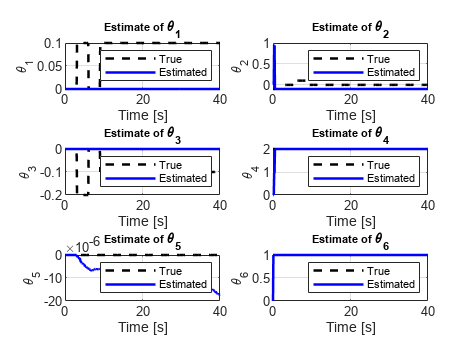


% Plot estimated parameters over time
figure;
for kidx = 1:n_params
    subplot(3,2,kidx);
    plot(t_vec, theta_true(kidx,:), 'k--', 'LineWidth',1.5); hold on;
    plot(t_vec, theta_hat(kidx,:), 'b', 'LineWidth',1.5);
    xlabel('Time [s]');
    ylabel(['\theta_',num2str(kidx)]);
    legend('True','Estimated');
    title(['Estimate of \theta_',num2str(kidx)]);
    grid on;
end

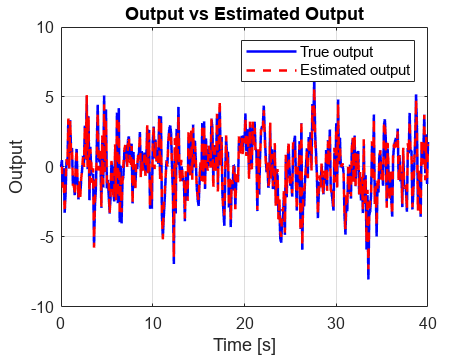


% Plot output vs estimated output
figure;
plot(t_vec, y, 'b', 'LineWidth',1.5); hold on;
plot(t_vec, y_hat, 'r--', 'LineWidth',1.5);
xlabel('Time [s]');
ylabel('Output');
legend('True output','Estimated output');
title('Output vs Estimated Output');
grid on;

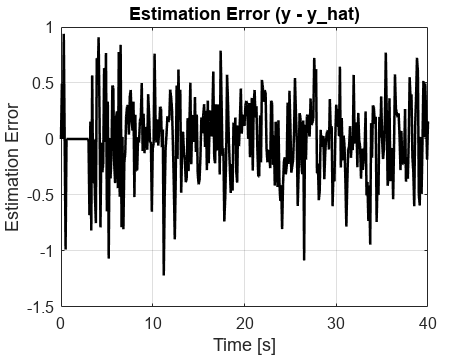


% Compute error
error = y - y_hat;

% Plot error
figure;
plot(t_vec, error, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Estimation Error');
title('Estimation Error (y - y\_hat)');
grid on;

RLS

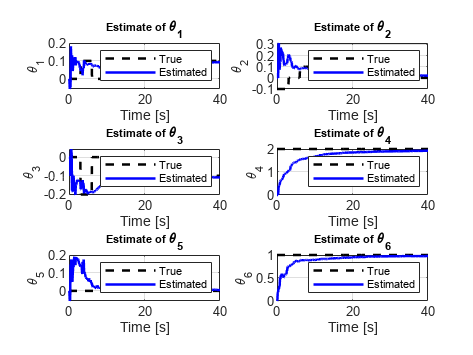

% Initialize estimated output y_hat
y_hat = zeros(T,1);

% Initialize parameter estimate
theta_hat = zeros(n_params, T);
theta_hat(:,1) = zeros(n_params,1);

% Initial covariance matrix P
k = 10;
P_prev = (1/k) * eye(n_params);

% RLS loop
for t_idx = 1:T
    % Build regressor phi(t)
    phi = zeros(n_params,1);
    if t_idx >=2
        phi(1) = y(t_idx-1);
        phi(6) = u(t_idx-1);
    end
    if t_idx >=3
        phi(2) = y(t_idx-2);
        phi(5) = u(t_idx-2);
    end
    if t_idx >=4
        phi(3) = y(t_idx-3);
        phi(4) = u(t_idx-3);
    end

    % Generate true output y(t)
    y(t_idx) = theta_true(:, t_idx)' * phi;

    % Skip parameter update if no past data
    if t_idx == 1
        continue
    end

    % Compute prediction error
    e = y(t_idx) - phi' * theta_hat(:, t_idx-1);

    % Compute gain denominator
    denom = 1 + phi' * P_prev * phi;

    % Compute gain K(t)
    K = (P_prev * phi) / denom;

    % Update parameter estimate
    theta_hat(:, t_idx) = theta_hat(:, t_idx-1) + K * e;

    % Update covariance matrix
    P_new = P_prev - (K * phi' * P_prev);

    % Store estimated output (using theta_hat before update)
    y_hat(t_idx) = phi' * theta_hat(:, t_idx-1);

    % Update covariance for next iteration
    P_prev = P_new;
end

% Plot parameter estimates over time
figure;
for kidx = 1:n_params
    subplot(3,2,kidx);
    plot(t_vec, theta_true(kidx,:), 'k--', 'LineWidth',1.5); hold on;
    plot(t_vec, theta_hat(kidx,:), 'b', 'LineWidth',1.5);
    xlabel('Time [s]');
    ylabel(['\theta_',num2str(kidx)]);
    legend('True','Estimated');
    title(['Estimate of \theta_',num2str(kidx)]);
    grid on;
end

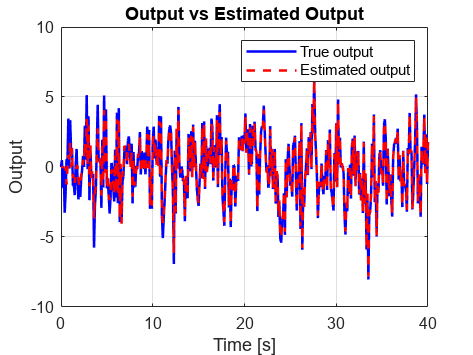


% Plot output vs estimated output
figure;
plot(t_vec, y, "b", 'LineWidth',1.5); hold on;
plot(t_vec, y_hat, 'r--', 'LineWidth',1.5);
xlabel('Time [s]');
ylabel('Output');
legend('True output','Estimated output');
title('Output vs Estimated Output');
grid on;

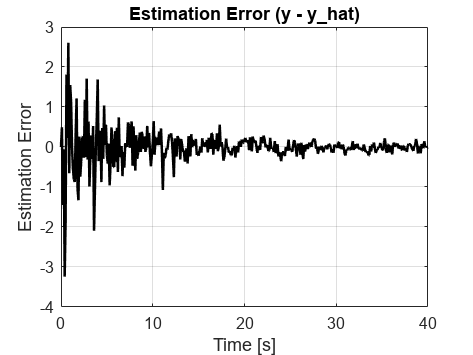


% Compute error
error = y - y_hat;

figure;
plot(t_vec, error, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Estimation Error');
title('Estimation Error (y - y\_hat)');
grid on;